# Bit-to-complex-symbol mapping for IQ Modulations

This functions maps a bit stream into a complex symbol stream with respect to some IQ constellations.

**Inputs:**

- *bit_TX*: bit stream vector of size *nb_bit x 1*

- *nb_bit_per_symb*: number of bits per symbol

- *nb_bit*: number of bits in the input bit stream (= length of *bit_TX*)

**Ouputs:**

- *symb_TX*: complex symbol stream vector of size *nb_symb x 1* where *nb_symb = nb_bit / nb_bit_per_symb*

function symb_TX = mapping_QAM( bit_TX , nb_bit_per_symb , nb_bit )

if rem( nb_bit , nb_bit_per_symb ) ~= 0
    error('issue: the data stream is not an integer number of symbols')
end

nb_symb = nb_bit / nb_bit_per_symb ;                                % Number of symbols of the data stream
symb_TX = zeros( nb_symb , 1 ) ;                                   % Symbol stream vector initialization

## 4QAM constellation (<=> QPSK)

The mapping for the QPSK constellation should be done as shown below:

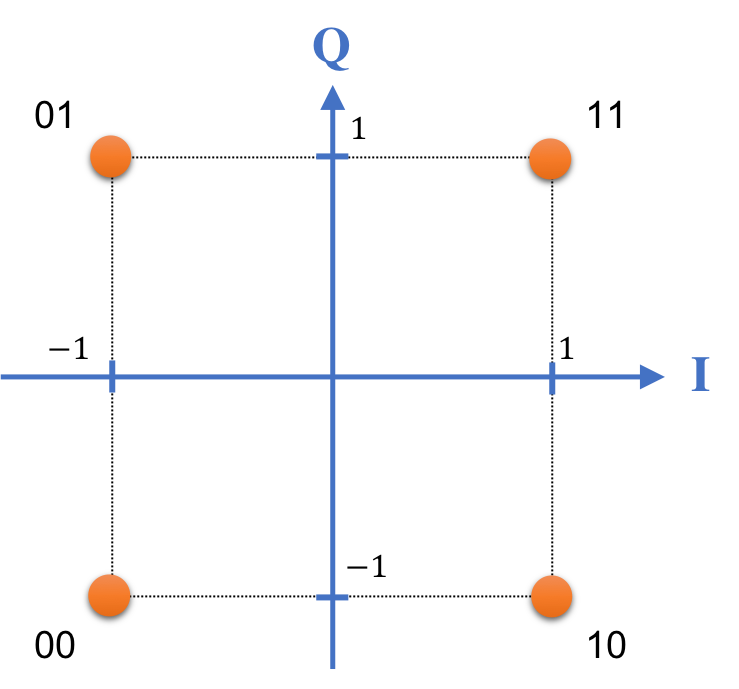

This mapping follows a gray coding: each symbol differs from its neighbors by one bit only. This reduces bit errors as a received symbol distorted by some noise is more likely to fall close to an adjacent symbol  than close to a faraway symbol. 

if nb_bit_per_symb == 2
    
    QAM_4 = [-1-1i, -1+1i, 1+1i, 1-1i];
    
    
    bit_pairs = reshape(bit_TX, 2, nb_symb).'; 
    
    
    for i = 1:nb_symb
        bit_pair = bit_pairs(i, :);
        % Mapping based on Gray coding
        if isequal(bit_pair, [0 0])
            symb_TX(i) = QAM_4(1);  % 00 -> -1 - 1i
        elseif isequal(bit_pair, [0 1])
            symb_TX(i) = QAM_4(2);  % 01 -> -1 + 1i
        elseif isequal(bit_pair, [1 1])
            symb_TX(i) = QAM_4(3);  % 11 -> 1 + 1i
        elseif isequal(bit_pair, [1 0])
            symb_TX(i) = QAM_4(4);  % 10 -> 1 - 1i
        end
    end
end

## 16QAM constellation

The mapping for the 16QAM constellation should be done as shown below:

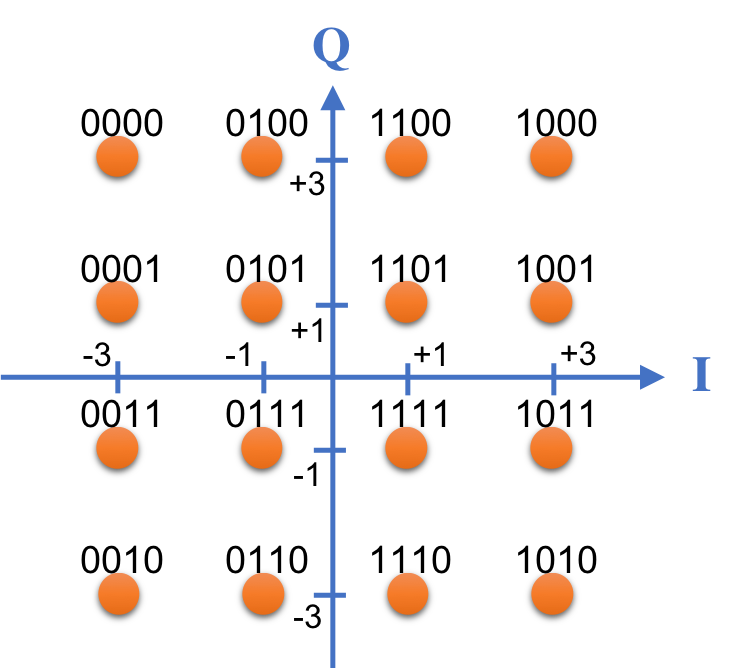

This mapping follows a gray coding: each symbol differs from its neighbors by one bit only. This reduces bit errors as a received symbol distorted by some noise is more likely to fall close to an adjacent symbol  than close to a faraway symbol. 

if nb_bit_per_symb == 4
    %Qam_16 =   0000 ,  0001 ,  0010 ,  0011 ,  0100 ,  0101 ,  0110 ,  0111 , 1000 , 1001 , 1010 , 1011 , 1100 , 1101 , 1110 , 1111  
    QAM_16 = [ -3+3i , -3+1i , -3-3i , -3-1i , -1+3i , -1+1i , -1-3i , -1-1i , 3+3i , 3+1i , 3-3i , 3-1i , 1+3i , 1+1i , 1-3i , 1-1i ];
    
    
    bit_pairs = reshape(bit_TX, 4, nb_symb).'; 
    
    
    % Map each 4-bit group to the corresponding 16-QAM symbol
    for i = 1:nb_symb
        bit_pair = bit_pairs(i, :);
        % Convert the bit pair to a decimal index
        idx = bi2de(bit_pair, 'left-msb') + 1; % 'left-msb' means the leftmost bit is the most significant
        % Assign the corresponding QAM symbol
        symb_TX(i) = QAM_16(idx);
    end




end

end